# Cleaning, Re-referencing, and Removing Artifacts from EEG

In this livescript, we will clean the data using a bandpass filter, artifact subspace reconstruction (ASR), and independent component analysis, all of which we perform using EEGLAB functions. Most of the process are complex and may be computationally intensive. With batch processing, it may take a while, so we will install a EEGLAB plugin to batch process datasets using the [**Neuroscience Gateway Portal**](https://github.com/sccn/nsgportal), a way to run EEGLAB scripts using high-performance computing resources. We will go through using this resource in a later tutorial.

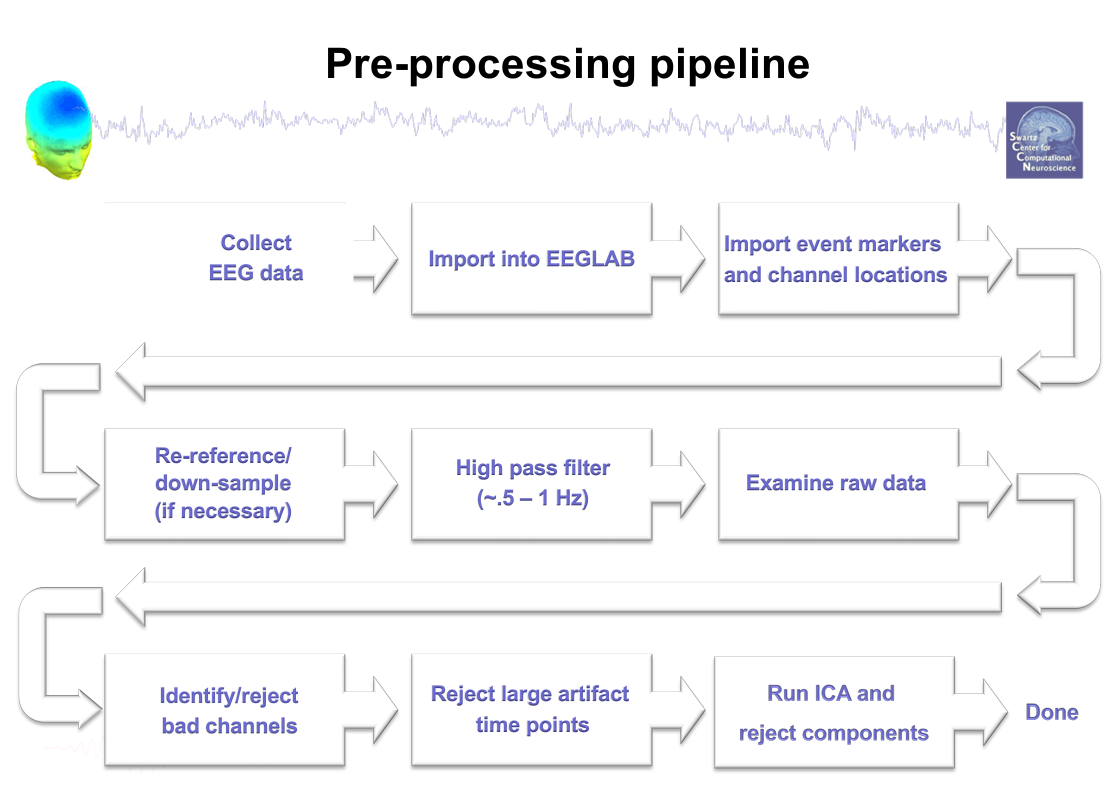

## Visualizing our Uncleaned Data

Before we do any cleaning, let's load in our data (we saved from the last tutorial) and visualize the raw data. The following code block will look familiar: 

%% Change this to the path where eeglab folder is
%eeglab_path = fullfile(matlabroot,'toolbox','eeglab');
%addpath(genpath(eeglab_path));

%Initializing EEGlab
eeglab;

%Directory where are data are located: 
dir_data = 'data'; %Change this to where your data is

%Directory where our LSL recordings are located: 
dir_xdf = fullfile(dir_data,'xdf');

%Directory where headset data are located: 
dir_head = fullfile(dir_data,'headset_channel_locations');

%Directory where we will save our data: 
dir_set = fullfile(dir_data,'set');

%Using an if/else statement to check if folder already exists: 
if not(isfolder(dir_set))
    fprintf('Creating a new folder at %s',dir_set);
    mkdir(dir_set); % if the folder doesn't exist, we will create it
    disp('Done!')
else
    fprintf('%s already exists!',dir_set)
end

Let's load our saved set dataset: 

%Format specifier for our recording: 
file_spec = 'vrcct_%s_%s_%s.%s'; %Four char formatting operators

%Let us define the name parts of our file: 
sub = 'p16'; %subject or participant 16
study = 'prestudy'; %First session of experiment
part = 'condition_raw'; %meditation part of session
ext = 'set'; %File extension of our dataset (Set file)

%Let us use sprintf to define a dataset name: 
file_name = sprintf( ...
    file_spec, ...
    sub,study,part,ext);

%Loading Set file
EEG = pop_loadset( ...
    'filename',file_name, ...
    'filepath',dir_set);

Visualizing our raw data using the pop_eegplot (the y axis is voltage and x axis is time in seconds): 

figure; 
pop_eegplot(EEG,1,1,0);

If you scroll through the data and increase the amplitude range with the plus sign on the bottom right, you will see only lines. Before we can actually see typical EEG signals, we need to clean the data with a bandpass filter. Then we can re-reference the data to a common reference (e.g. average or channel reference). Finally, we can apply ASR and ICA to remove any bad channels and any artifacts.

## Bandpass Filter

A bandpass filter is a device that passes frequencies within a certain range and attenuates frequences outside that range. We usually apply a bandpass filter between 1 Hz and 50 Hz, but could vary depending on your experiment and headset. That is, when we apply this type of bandpass filter, only frequencies between 1 Hz to 50 Hz are kept in the data. We use the function **pop_eegfiltnew** that takes in three inputs to apply a bandpass filter: EEG struct, low cutoff frequency (i.e. 1 Hz), and high cutoff frequency (i.e. 50 Hz). The output is a filtered EEG struct. It is pretty straight-forward using it: 

%Cutoffs:
low_cutoff = 1; %Hz
high_cutoff = 50; %Hz

%Bandpass filtering between 1 to 50 Hz
EEG = pop_eegfiltnew( ...
    EEG, low_cutoff, high_cutoff); 

## Re-refencing EEG Data

A common way to re-reference involves using a common reference channel or an average reference. In this dataset, we don't have a reference channel (e.g. M1 and M2 on the mastiods). Your reference will affect your data. When using your reference, it is important to consider the comparability to other studies. If you want to compare results from another study, it is wise to use the same reference they used. You can refer to this [**resource**](https://pressrelease.brainproducts.com/referencing/) as it mentions the difference between average mastiods and common average reference. I would recommend reading that information. 

We will use the **pop_reref** function and it takes in two inputs: the EEG struct and the reference channel, if any as a cell array of channel labels (i.e. {'M1','M2'}). Let's re-reference our data: 

% Reference channels (we don't have any):
reference_chan = {};

% Using an if/else statement to apply a channel(s) or average reference:
if ~isempty(reference_chan)
    %Channel reference ('M1','M2')
    EEG = pop_reref(EEG, reference_chan);
else
    %Average Re-reference
    EEG = pop_reref(EEG, []);
end

With a bandpass filter and re-referencing the EEG, let's visualize it : 

figure; 
pop_eegplot(EEG,1,1,0);

We can actually see 

## Artifact Subspace Reconstruction

[**Artifact subspace reconstruction (ASR)**](https://ieeexplore.ieee.org/document/8768041/authors#authors) is an automatic, online-capable, and component-based method that can effectively remove transient or large-amplitude artifacts contaminating EEG data. This is a way to automate artifact removal with a single function (with other applications): [**clean_rawdata**](https://github.com/sccn/clean_rawdata). This function can remove bad channels and bad portions of data. There are various inputs for this function (all taken from the documentation): 

- **EEG** struct you want to remove artifacts from.

- **Flatline Criterion**: maximum tolerated flatline duration in seconds. If a channel has a longer flatline than this, it will be considered abnormal and removed (Default: 5). 

- **High Pass Criterion**: Applies a high-pass filter and is formatted as [transition-start, transition-end]. (Default: [0.25 0.75]). We can disable it with a value of -1. 

- **Channel Criterion**: Minimum channel correlation. If a channel is correlated at less than this vlaue to a reconstruction of it based on other channels, it is considered abnormal in the given time window and will be removed. This method requires taht channel locations are available and roughly correct. (Default: 0.85).

- **Line Noise Criterion**: Line noise refers to random fluctuations-electrical impulses that are carried along with standard AC current. If a channel has more line noise relative to its signal than this value, in standard deviation units based on the total channel population, it is considered abnormal and removed. (Default: 4).

- **Burst Criterion** **(ASR)**: It is out of the scope of this tutorial to explain ASR fully, so please refer to the resource for ASR in the beginning of this section. The value for this input is a standard deviation cutoff for removal of bursts (via ASR). ASR may be used to correct bad portions of data or to remove them. First, ASR finds clean portions of data (calibration data) and calculates PCA-extracted components’ standard deviation (ignoring physiological EEG alpha and theta waves by filtering them out). It rejects data regions if they exceed 20 times (by default) the standard deviation of the calibration data. The lower this threshold, the more aggressive the rejection is. (Default: 20 in GUI and 5 in function).

- **Window Criterion**: Criterion for removing time windows that were not repaired completely. This may happen if the artifact in a window was composed of too many simultaneous  uncorrelated sources (for example, extreme movements such as jumps). This is the maximum fraction of contaminated channels that are tolerated in the final output data for each considered window. Generally a lower value makes the criterion more aggressive. Default: 0.25. Reasonable range: 0.05 (very aggressive) to 0.3 (very lax).

Let's apply this function with the values I use normally. These values may change depending on your experiment and ask your principal investigator or someone more experienced for guidance. 

%ASR parameters for bad channels
threshFlatChannel = 5; % max tolerated flatline duration in seconds
highPassBand = -1; %Disabled but default is [0.25,0.75]
threshPoorCorrChannel = 0.7; %min channel correlation
threshLineNoiseChannel = 4; %line noise relative to its signal in std. units
threshASR = 20; %Std. cutoff for removal of burst via ASR; 5 is more aggressive.
threshWindow = -1; %Disabled but this parameter remove time windows that are not completely repaired.

%Saving EEG data with artifacts:
EEG_raw = EEG; 

%Applying clean_rawdata: 
EEG = clean_rawdata( ...
    EEG, ...
    threshFlatChannel, ...
    highPassBand, ...
    threshPoorCorrChannel, ...
    threshLineNoiseChannel, ...
    threshASR, ...
    threshWindow);

We can compare the artifact-free data with artifact-laden data using vis_artifacts: 

figure; 
vis_artifacts(EEG,EEG_raw); %Blue is clean and Red is raw

It looks like it got rid of a lot of eye blinks, but please understand that no algorithm is perfect, and the data may still have some artifacts. This is why we use Independent Component Analysis (ICA) to get rid of even more artifacts. 

## Independent Component Analysis

ICA is a computational method for separating a multivariate signal into additive subcomponents, allowing us to remove/subtract artifacts embedded in the data (muscle, eye blinks, or eye movements) without removing the affected data portions. If you are interested in ICA, please refer to this [**video playlist**](https://youtube.com/playlist?list=PLXc9qfVbMMN2uDadxZ_OEsHjzcRtlLNxc), this part of the [**ECGLAB tutorial**](https://eeglab.org/tutorials/06_RejectArtifacts/RunICA.html), and this [**appendix part**](https://eeglab.org/tutorials/ConceptsGuide/ICA_background.html) for more information. It is complex process, but for our purposes, we only need to know how to use it to get rid of artifacts. The algorithm we use is [**runica**](https://github.com/sccn/eeglab/blob/develop/functions/sigprocfunc/runica.m). Additionally, we perform an extended ICA using the extended input. To run ica, we use the function **pop_runica **that takes in three inputs (output will be a EEG struct): 

- EEG struct

- icatype: we will run 'runica'

- extended: We will run an extended ICA using the value of 1 (True)

This is a computationally intensive process and may take a while depending on your computer. We run it with the following code:

%Computationally intensive, so run at your own risk!
EEG = pop_runica(EEG,'icatype','runica','extended',1);

Now comes the artifact labeling, artifact flagging, and artifact removal. In this next part, we will label each component into different artifacts: Brain, Muscle, Eye, Heart, Line Noise, Channel Noise, and Other. The algorithm is based on experimental data. The function we use is** pop_iclabel**, which takes in the EEG struct. You can view more information [**here**](https://labeling.ucsd.edu/tutorial/about) (as well as training you how to label EEG components). 

We can then flag them using probabilities that ranges from 0 to 1 (0 being improbable and 1 being completely true). The function **pop_icflag** that takes in the EEG struct and a 7x2 array with probability thresholds to include for selection as artifacts. The seven artifact categories are Brain, Muscle, Eye, Heart, Line Noise, Channel Noise, and Other. 

Finally, we can reject any flagged components (flagged as artifacts) using the function **pop_subcomp**. It takes in the EEG struct and the index of components flagged as artifacts (from pop_icflag). 

Let's perform and remove artifacts: 

%Artifact Probability Thresholds
thresh_artifacts = [
    NaN, NaN; % Brain
    0.8, 1.0; % Muscle
    0.8, 1.0; % Eye
    0.8, 1.0; % Heart
    0.8, 1.0; % Line Noise
    0.8, 1.0; % Channel Noise
    NaN, NaN]; % Other

%Labeling components if they are artifacts: 
EEG = pop_iclabel(EEG,'default');

%Flagging Artifacts: 
EEG = pop_icflag(EEG, thresh_artifacts);

%Removing any Artifacts: 
EEG = pop_subcomp(EEG,find(EEG.reject.gcompreject));

We can visualize it one last time and see what channels we have (and how clean it is): 

figure; 
pop_eegplot(EEG,1,1,0);

## Saving Clean Dataset

%Changing name to clean
part = 'condition_clean'

%Let us use sprintf to define a dataset name: 
file_name = sprintf( ...
    file_spec, ...
    sub,study,part,ext);

%Saving our dataset (overwriting the set file): 
EEG = pop_saveset( ...
    EEG, ...
    'filename',file_name, ...
    'filepath',dir_set, ...
    'savemode','twofiles');

## Conclusion

Some basic EEG processing includes applying a digital bandpass filter, applying ASR, and finally applying ICA. While these algorithms have been used by many researchers, it does not mean they are not perfect and do not get rid of all artifacts. We can additionally physically visualize the EEG and get rid of noise by eye, but that is subjective. Each researcher may have different criteria on what is considered noise/artifacts. There are some disadvatages to both automated and actively/physically removing noise/artifacts. i lean more on the automated side, but I think we should visualize the data to see if our data is not riddled by noise/artifacts after running an automated preprocessing script. In the next tutorial, we will cover epoch cleaning (which can be optional). Afterwards, there will be a tutorial to write a function to handle all our preprocessing (which will be an interactive exercise using all skills up until then). 